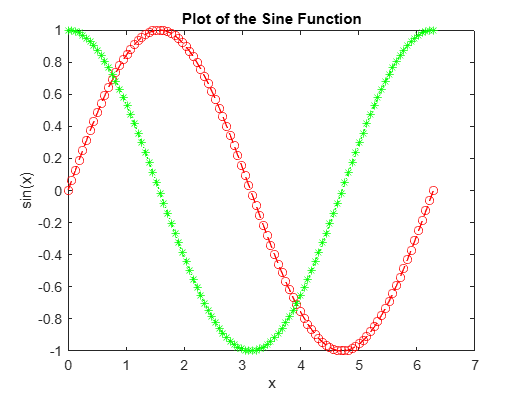

clc
x = linspace(0,2*pi,100);
y = sin(x);
plot(x,y,'--ro')

xlabel('x')
ylabel('sin(x)')
title('Plot of the Sine Function')

hold on
y2 = cos(x);
plot(x,y2,'g:*')
hold off


Y = magic(5)

Y =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


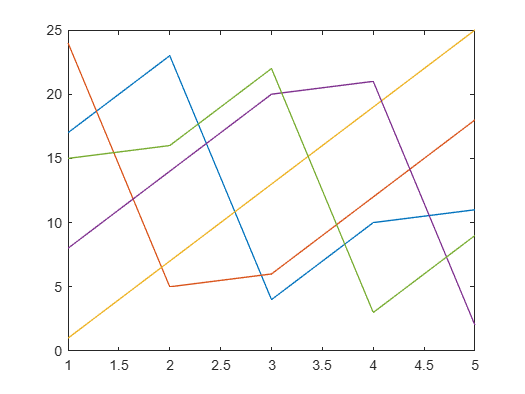

figure
plot(Y)


x = linspace(0,2*pi,25);
y = sin(x);
ln2 = plot(x,y)

ln2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2618 0.5236 0.7854 1.0472 1.3090 1.5708 1.8326 2.0944 2.3562 2.6180 2.8798 3.1416 3.4034 3.6652 3.9270 4.1888 4.4506 4.7124 4.9742 5.2360 5.4978 5.7596 6.0214 6.2832]
              YData: [0 0.2588 0.5000 0.7071 0.8660 0.9659 1 0.9659 0.8660 0.7071 0.5000 0.2588 1.2246e-16 -0.2588 -0.5000 -0.7071 -0.8660 -0.9659 -1 -0.9659 -0.8660 -0.7071 -0.5000 -0.2588 -2.4493e-16]

  Show all properties


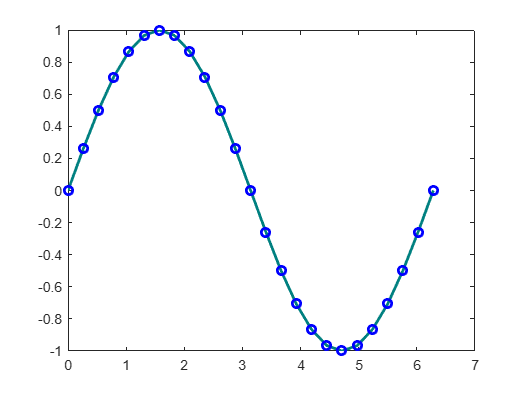

ln2.LineWidth = 2;
ln2.Color = [0 0.5 0.5];
ln2.Marker = 'o';
ln2.MarkerEdgeColor = 'b';

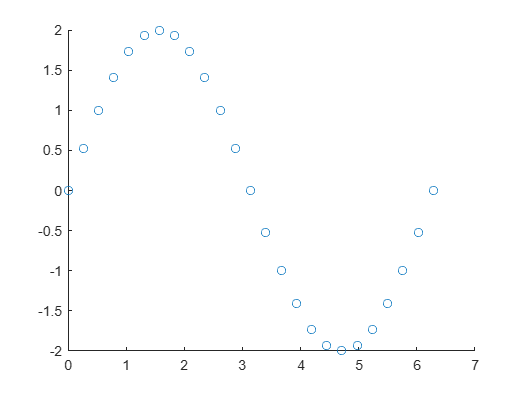


y3 = 2*sin(x);
scatter(x,y3)

x = linspace(0,10,50);
y1 = sin(x);
y2 = rand(50,1);
tiledlayout(2,1)

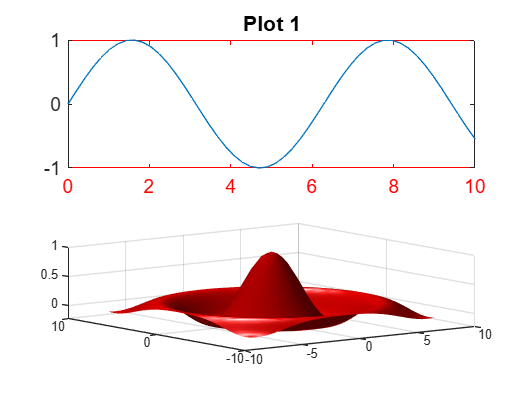

nexttile
plot(x,y1)
title('Plot 1')
nexttile
scatter(x,y2)
title('Plot 2')


x = linspace(0,10,50);
y1 = sin(x);
y2 = rand(50,1);
% Top two plots
tiledlayout(2,2)
nexttile
plot(x,y1)
nexttile
scatter(x,y2)
% Plot that spans
nexttile([1 2])
y2 = rand(50,1);
plot(x,y2)


x = linspace(0,10,50);
y1 = sin(x);
y2 = rand(50,1);
tiledlayout(2,1)
% Top plot
ax1 = nexttile;
plot(ax1,x,y1)
title(ax1,'Plot 1')
ax1.FontSize = 14;
ax1.XColor = 'red';
% Bottom plot
ax2 = nexttile;
scatter(ax2,x,y2)
title(ax2,'Plot 2')
grid(ax2,'of')

x = linspace(0,25);
y = sin(x/2);
yyaxis left
plot(x,y);

r = x.^2/2;
yyaxis right
plot(x,r);


yyaxis right
cla reset
load count.dat;
m = mean(count,2);
e = std(count,1,2);
errorbar(m,e)

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
colorbar

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
alpha(.4)

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z,'FaceColor','red','EdgeColor','none')
camlight left;
lighting phong